clc,clear,close all

a = 1/(16*pi^2);
T = 1;
x1 = 0;
x2 = 1;
u1 = @(t) 0;
u2 = @(t) 0;
g1 = @(x) 0;    % 
g2 = @(x) sin(4*pi*x);            % 导数初值条件
uu = @(x,t) sin(t)*sin(4*pi*x);

tau = 0.0001;
h = 0.001;

xx = x1:h:x2;
lambda = tau^2/h^2;
if a*lambda>1
    warning('方法不稳定')
end
m = (x2-x1)/h+1;
n = T/tau+1;
u = zeros(n,m);
u(1,:) = g1(xx);
u(2,1) = u1(tau);
u(2,2:end-1) = 1/2*a*lambda^2*(u(1,1:end-2)+u(1,3:end))+(1-a*lambda^2)*u(1,2:end-1)+tau*g2(xx(2:end-1));
u(2,end) = u2(tau);
for i = 3:n
    temp1 = u1((i-1)*tau);
    temp2 = a*lambda*(u(i-1,1:end-2)-2*u(i-1,2:end-1)+u(i-1,3:end))+2*u(i-1,2:end-1)-u(i-2,2:end-1);
    temp3 = u2((i-1)*tau);
    temp = [temp1,temp2,temp3]';
    u(i,:) = temp;
end

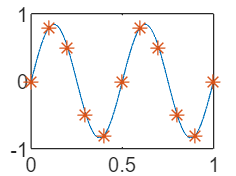

plot(xx,u(end,:))
hold on
xx = x1:0.1:x2;
plot(xx,uu(xx,T),'*')
hold off